clear all
close all
clc

Kp = 1;
Ki = 0;

%PI = PIController_pos(0.001,Kp,Ki);
PI = PIController_vel(0.001,Kp);
PI.starting();
s=tf('s');
pi = Kp*(1+Ki/s);
piz = c2d(pi,0.001);
G = 1/(1+s)

G =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



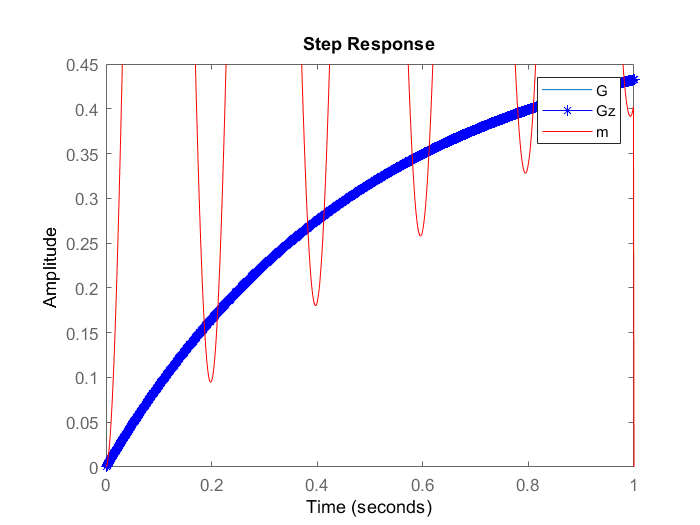

Gz =c2d(G,0.001);
figure
opt = stepDataOptions('StepAmplitude',1);
%step(feedback(pi*G,1),opt)
step(feedback(pi*G,1),1,opt)
hold on
[yz,t]=step(feedback(piz*Gz,1),1,opt);
plot(t,yz,'-*b')



testREF = ones(1,1001);
y = zeros(1,1001);
ucontrol = zeros(1,1001);
for i =2:1:1000
    %ucontrol(i) = testREF(i)-y(i-1);
    ucontrol(i) = PI.computeControlAction(testREF(i),y(i-1));
    
    y(i) = 0.0009995*ucontrol(i) + 0.999*y(i-1);
end
%figure
%plot(ucontrol)7
temp = (0:0.001:1);
plot(temp,y,'-r')
legend("G","Gz","m")

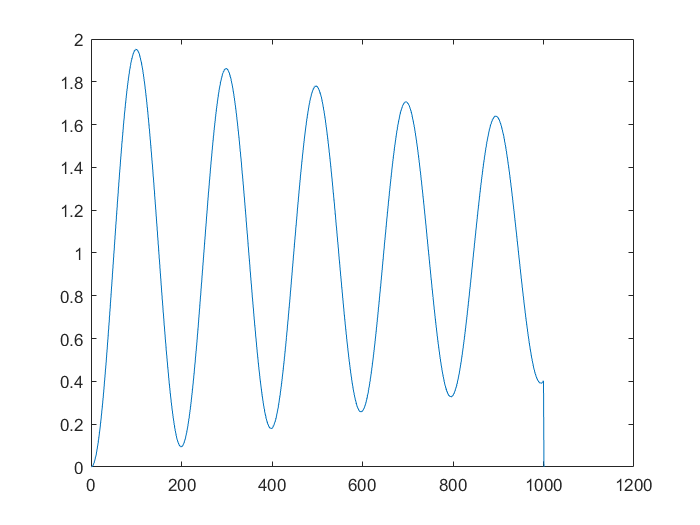

figure
plot(y)

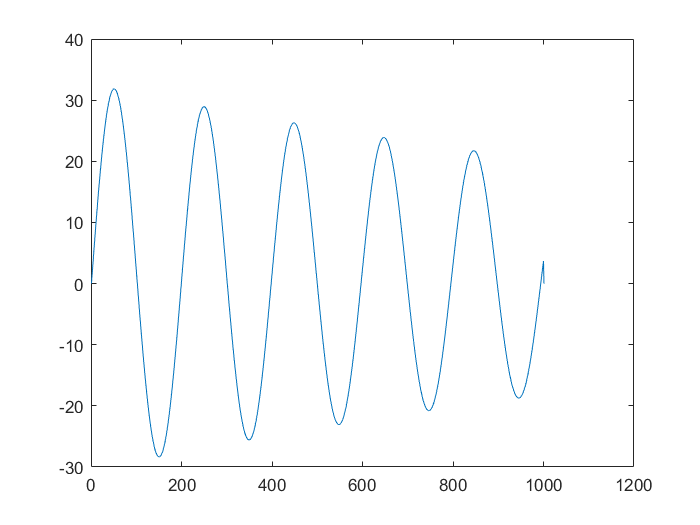

plot(ucontrol)

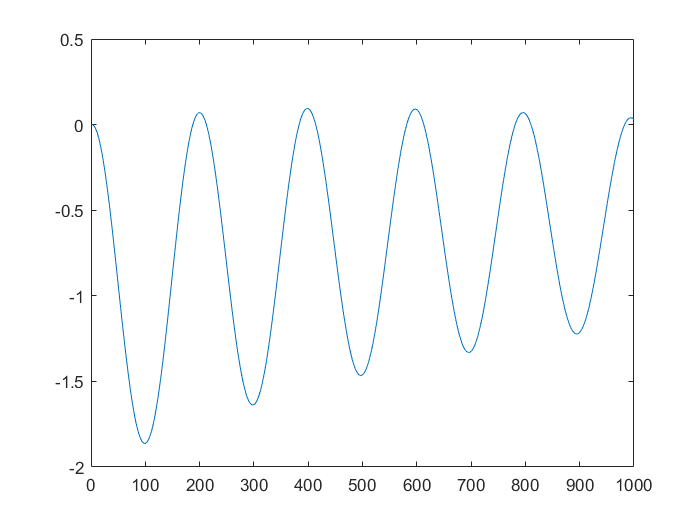

plot(yz(1:end-1)'-y(1:end-1))